# Example: Solver for Acoustics in 2D with Multipole Sources

This live-script features the following:

- 2D example

- how to set up multipole sources

In 2D, mutipole sources are of the form


$$f(x,y,t) = \sum_{m=1}^M w_m(t) D^{\mathbf s_m}\delta(x-x_{m},y-y_m)$$


where 

- $w_m(t)$ is the time function of the $m$-th term

- $\mathbf s_m\in\mathbb N^2$ is the derivative order of the $m$-th term

- $D^{\mathbf s_m}\delta(x-x_m,y-y_m)$ is the $\mathbf s_m$-mixed derivative of the Dirac delta function shifted by $(x_m,y_m)$

- $(x_m,y_m)$ is the center/location of the $m$-th term

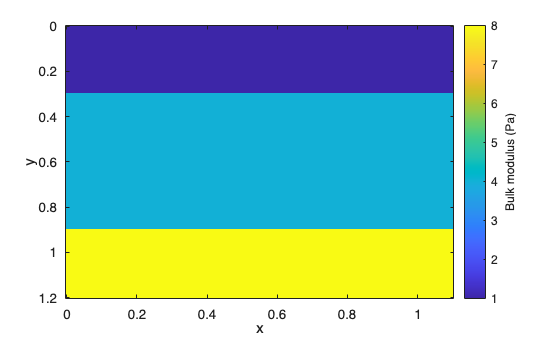

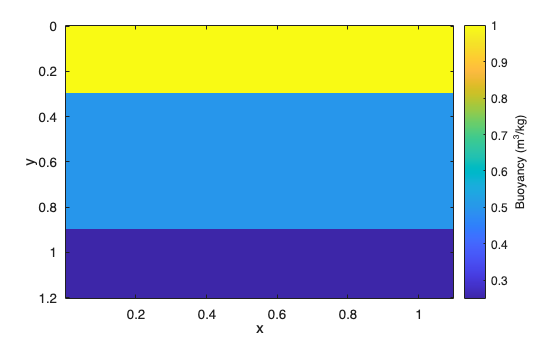

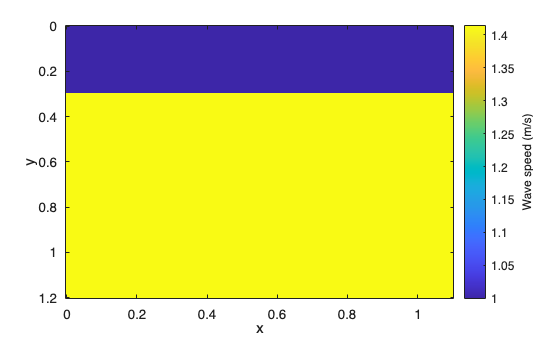

clear

domain_x = [0,1.1];
domain_y = [0,1.2];
domain_t = [0,1];

% Computational grids and grid spaces
Nx = 151;
Ny = 161; 
grid_x_primal = Grid1DUnifPrimal(domain_x,Nx);
grid_y_primal = Grid1DUnifPrimal(domain_y,Ny);
grid_x_dual   = Grid1DUnifDual(grid_x_primal);
grid_y_dual   = Grid1DUnifDual(grid_y_primal);
gsp_P  = GridSpace2D(grid_x_primal, grid_y_primal);
gsp_Vx = GridSpace2D(grid_x_dual,   grid_y_primal);
gsp_Vy = GridSpace2D(grid_x_primal, grid_y_dual);
h = gsp_P.h; %spatial grid sizes, h = [dx,dy]

% Acoustic medium parameters
medium = AcousticMedium2D.layeredY( ...
    BetaValues=[1,0.5,0.25], ...
    KappaValues=[1,4,8], ...
    Domain=[domain_x;domain_y], ...
    RelativeWidths=[0.25,0.5,0.25]);
[kappa,beta_x,beta_y,wspeed,cMax] = sampleMedium2D(gsp_P,medium);

wspeed.plot;


% Time grid (computed after medium)
CFL_factor = 0.9;
dt = CFL_factor*(6/7)/(cMax*sqrt(sum(1./gsp_P.h.^2))); %CFL condition for 2-4 FDM
Nt = ceil(diff(domain_t)/dt)+1;
dt = diff(domain_t)/(Nt-1); %recomputing to ensure time domain divisible by dt
t_pts = domain_t(1):dt:domain_t(2);

% Output grid and times
gsp_out = GridSpace2D( ...
    Grid1DUnifPrimal(domain_x,101), ...
    Grid1DUnifPrimal(domain_x,101));
t_pts_out = linspace(domain_t(1),domain_t(2),81);

% Initial conditions
p0 = @(x,y) zeros(size(x));
vx0 = @(x,y) zeros(size(x));
vy0 = @(x,y) zeros(size(x));

% Initializing PML
pml = PML2D( ...
    WidthLeft=0.15, ...
    WidthRight=0.15, ...
    WidthBottom=0.15, ...
    WidthTop=0.15);

% Initializing solver
solver = AcousticSolver2D_PML( ...
    gsp_P,times, ...
    gsp_out,t_pts_out, ...
    medium,pml, ...
    SpatialOrder=4);

Here we initialize several examples of multipole pressure sources.

Single term monopole: $w_0(t)\delta(x-x_0)$


% Define two pressure multipoles
% An order-zero pressure monopole at (0.35,0.45).
monopole = MultipoleTerm2D( ...
    [0.35,0.45],[0,0], ...
    @(t) exp(-((t-0.10)/0.025).^2), ...
    Amplitude=1,TargetField="pressure");

% An x-derivative of delta at (0.65,0.55). The factor multiplying the
% dipole is proportional to the grid spacing so that its discrete strength
% is visually comparable with that of the monopole.
xDipole = MultipoleTerm2D( ...
    [0.65,0.55],[1,0], ...
    @(t) exp(-((t-0.18)/0.035).^2), ...
    Amplitude=gsp_P.h(1),TargetField="pressure");

% Construct the multipole collection and discretize it on the three
% staggered computational grids.
multipole = MultipoleSeries2D( ...
    [monopole,xDipole],ApproximationOrder=4);
source = multipole.discretize( ...
    gsp_P,gsp_Vx,gsp_Vy);









% Run the solver
[P,Vx,Vy] = solver.solve(p0,vx0,vy0,Source=source);

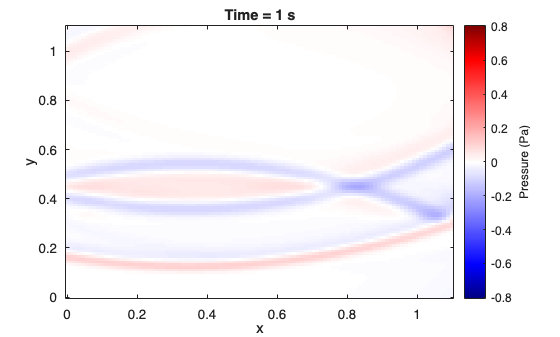

% Animate pressure
ax = axes(figure(Name="Pressure generated by 2D multipoles"));
P.animate(Parent=ax,relLimFactor=0.1);

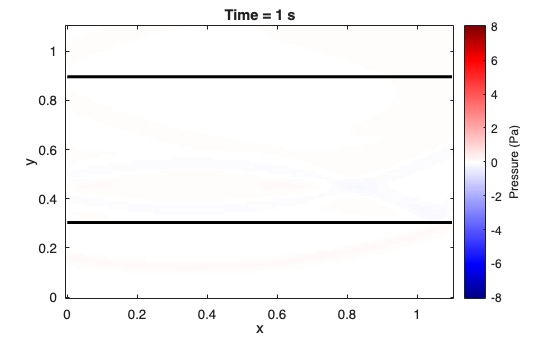

P.animateMedBack(medium,NumContours=11);